%Fecha de actualizacion 14/abril/2023
%clc
%clear all

# Ejemplos de modelos No Supervisados

%****
%En este ejercicio solo estaremos trabajando con un archivo
%contenido dentro del datastore
%****

%%%
%Creacion de directorio de trabajo
%rootFolder = 'D:\TSISB_IA';
rootFolder ='D:\MATLAB_Drive_esc\TSISB_IA';
workingFolder = 'practica_3';
tempFolder = 'temp';
savePath = fullfile(rootFolder,workingFolder);
saveTempPath = fullfile(rootFolder,workingFolder,tempFolder);

prefix = ['\' 'students'];
sufix = '.csv';
newName = [prefix, sufix];
%Despues de correr esta celda una vez, crea un bloque de comentarios a partir de esta linea

if ~exist(savePath,'dir')
    [status, message, ~] = mkdir(savePath);
    if status == 0
        disp(message)
    end
end

if ~exist(saveTempPath,'dir')
    [status, message, ~] = mkdir(saveTempPath);
    if status == 0
        disp(message)
    end
end

%%%
%Organizacion y copia de archivos
[fileName, pathFileName] = uigetfile('C:\','*.txt' );

if isequal(fileName,0)
    disp('Se canceló la busqueda de archivos');
else
    disp(['El usuario seleccionó el archivo ', fullfile(pathFileName,fileName)]);
    [status, message, ~] = copyfile([pathFileName,fileName],[saveTempPath,newName]);
    if status == 0
        disp(message)
    else
        disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    end
end

El usuario seleccionó el archivo D:\Sistema\Descargas\Nueva carpeta (139)\exams.csv


El cual se movio a la dirección D:\MATLAB_Drive_esc\TSISB_IA\practica_3\temp


%}

archivoCSV = [saveTempPath, newName];
opts = detectImportOptions(archivoCSV);
disp([opts.VariableNames' opts.VariableTypes'])

    {'gender'                  }    {'char'  }
    {'race_ethnicity'          }    {'char'  }
    {'parentalLevelOfEducation'}    {'char'  }
    {'lunch'                   }    {'char'  }
    {'testPreparationCourse'   }    {'char'  }
    {'mathScore'               }    {'double'}
    {'readingScore'            }    {'double'}
    {'writingScore'            }    {'double'}



opts = setvaropts(opts,{'race_ethnicity','gender','parentalLevelOfEducation','lunch','testPreparationCourse'},'Type','categorical');
newValues = {'gender','race','parentalLevel','lunch','testPreparation','mathScore','readingScore','writingScore'};
opts.VariableNames = newValues;
opts.VariableNamingRule='preserve';

disp([opts.VariableNames' opts.VariableTypes'])

    {'gender'         }    {'categorical'}
    {'race'           }    {'categorical'}
    {'parentalLevel'  }    {'categorical'}
    {'lunch'          }    {'categorical'}
    {'testPreparation'}    {'categorical'}
    {'mathScore'      }    {'double'     }
    {'readingScore'   }    {'double'     }
    {'writingScore'   }    {'double'     }


dsStudents_1 = readtable(archivoCSV,opts);
head(dsStudents_1)

ans = 8×8 table
    gender     race        parentalLevel          lunch        testPreparation    mathScore    readingScore    writingScore
    ______    _______    __________________    ____________    _______________    _________    ____________    ____________
    female    group D    some college          standard           completed          59             70              78     
    male      group D    associate's degree    standard           none               96             93              87     
    female    group D    some college          free/reduced       none               57             76              77     
    male      group B    some college          free/reduced       none               70     

valGenero = dsStudents_1.gender;
labelsGenero = categories(valGenero)

labelsGenero = 2×1 cell array
    {'female'}
    {'male'  }


valRaza = dsStudents_1.race;
labelsRaza = categories(valRaza)

labelsRaza = 5×1 cell array
    {'group A'}
    {'group B'}
    {'group C'}
    {'group D'}
    {'group E'}


valPadres = dsStudents_1.parentalLevel;
labelsPadres = categories(valPadres)

labelsPadres = 6×1 cell array
    {'associate's degree'}
    {'bachelor's degree' }
    {'high school'       }
    {'master's degree'   }
    {'some college'      }
    {'some high school'  }


valDesayuno = dsStudents_1.lunch;
labelsDesayuno = categories(valDesayuno)

labelsDesayuno = 2×1 cell array
    {'free/reduced'}
    {'standard'    }


valPrecurso = dsStudents_1.testPreparation;
labelsPrecurso = categories(valPrecurso)

labelsPrecurso = 2×1 cell array
    {'completed'}
    {'none'     }


math = dsStudents_1.mathScore;
reading = dsStudents_1.readingScore;
writing = dsStudents_1.writingScore;

xVar = [math, reading, writing];
yVar = [math, reading, writing];
colors = [0      0.4470 0.7410;...
          0.8500 0.3250 0.0980;...
          0.9290 0.6940 0.1250;...
          0.4940 0.1840 0.5560;...
          0.6350 0.0780 0.1840;...
          0.4660 0.6740 0.1880];


fig01=figure;
hold on
h1 = gplotmatrix(xVar,yVar,valGenero,colors,'.s',10)

h1 =   3×3×2 Line array.

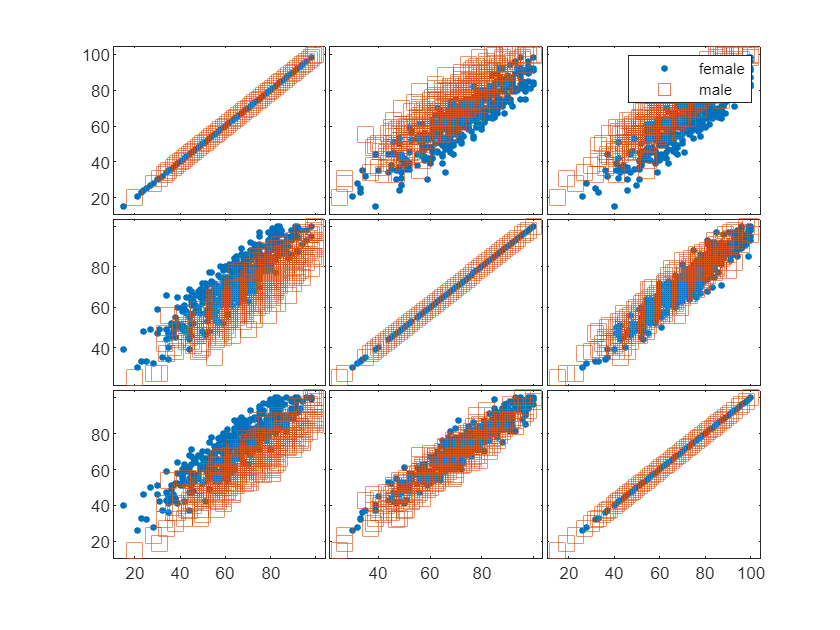

hold off

fig02 = figure;
hold on
h2 = gplotmatrix(xVar,yVar,valRaza,colors,'.*x^',5)

h2 =   3×3×5 Line array.

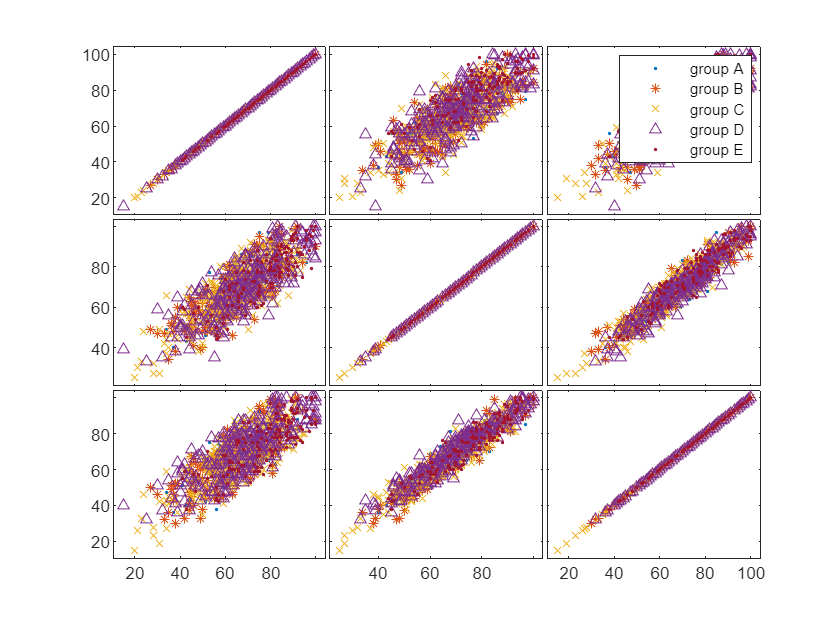

hold off

fig03 = figure;
hold on
h3 = gplotmatrix(xVar,yVar,valPadres,colors,'.*x^',5)

h3 =   3×3×6 Line array.

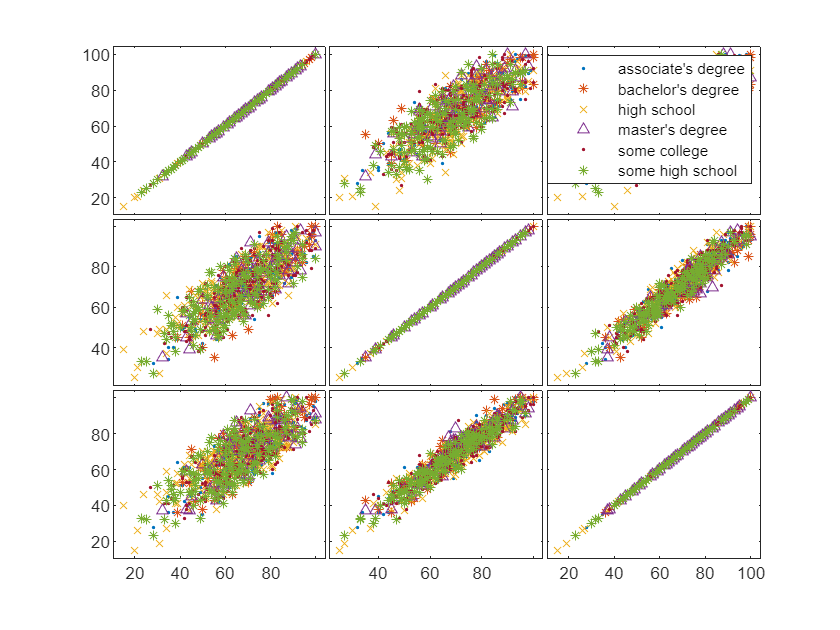

hold off


fig04 = figure;
hold on
h4 = gplotmatrix(xVar,yVar,valDesayuno,colors,'.*x^',5)

h4 =   3×3×2 Line array.

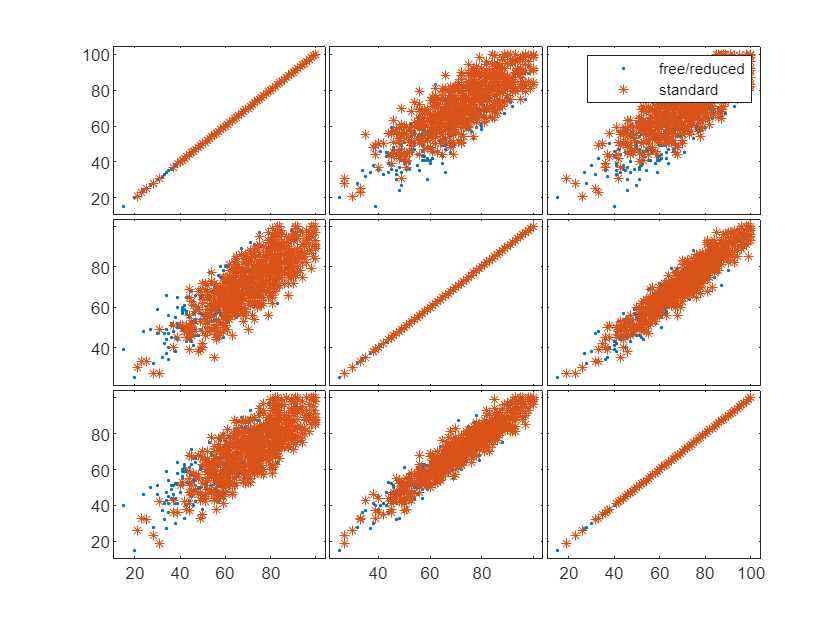

hold off


fig05 = figure;
hold on
h5 = gplotmatrix(xVar,yVar,valPrecurso,colors,'.*x^',5)

h5 =   3×3×2 Line array.

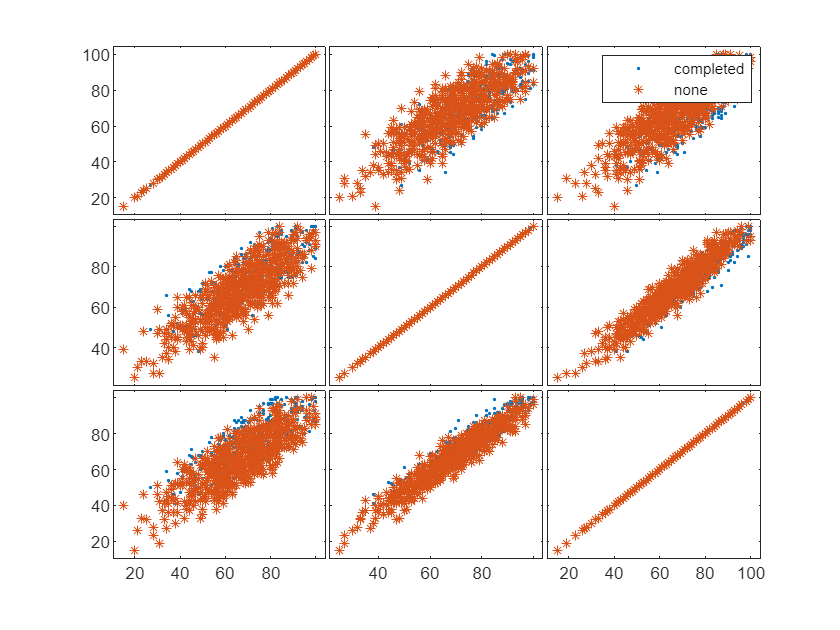

hold off

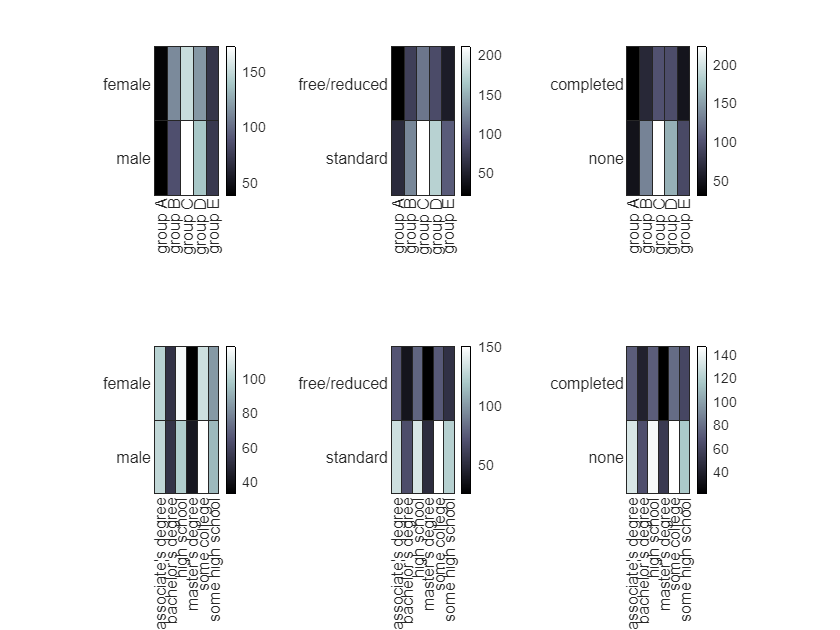

%Variables categoricas
%valGenero 2cat
%valRaza 5cat
%valPadres 5cat
%valDesayuno 2cat
%valPrecurso 2cat
%%%
%Etiquetas de variables
%labelsGenero
%labelsRaza
%labelsPadres
%labelsDesayuno
%labelsPrecurso
%%%
%Variables numéricas
%math
%reading
%writing

cts1 = crosstab(valGenero,valRaza);
cts2 = crosstab(valDesayuno,valRaza);
cts3 = crosstab(valPrecurso,valRaza);
cts4 = crosstab(valGenero,valPadres);
cts5 = crosstab(valDesayuno,valPadres);
cts6 = crosstab(valPrecurso,valPadres);

fig06=figure;
subplot(2,3,1)
    h1 = heatmap(labelsRaza,labelsGenero,cts1,'Colormap',bone);

subplot(2,3,2)
    h2 = heatmap(labelsRaza,labelsDesayuno,cts2,'Colormap',bone);
    %sortx(h2,'male')

subplot(2,3,3)
    h3 = heatmap(labelsRaza,labelsPrecurso,cts3,'Colormap',bone);
    %sortx(h3,'male')

subplot(2,3,4)
    h4 = heatmap(labelsPadres,labelsGenero,cts4,'Colormap',bone);
    %sortx(h4,'male')
subplot(2,3,5)
    h5 = heatmap(labelsPadres,labelsDesayuno,cts5,'Colormap',bone);
    %sortx(h5,'male')
subplot(2,3,6)
    h6 = heatmap(labelsPadres,labelsPrecurso,cts6,'Colormap',bone);

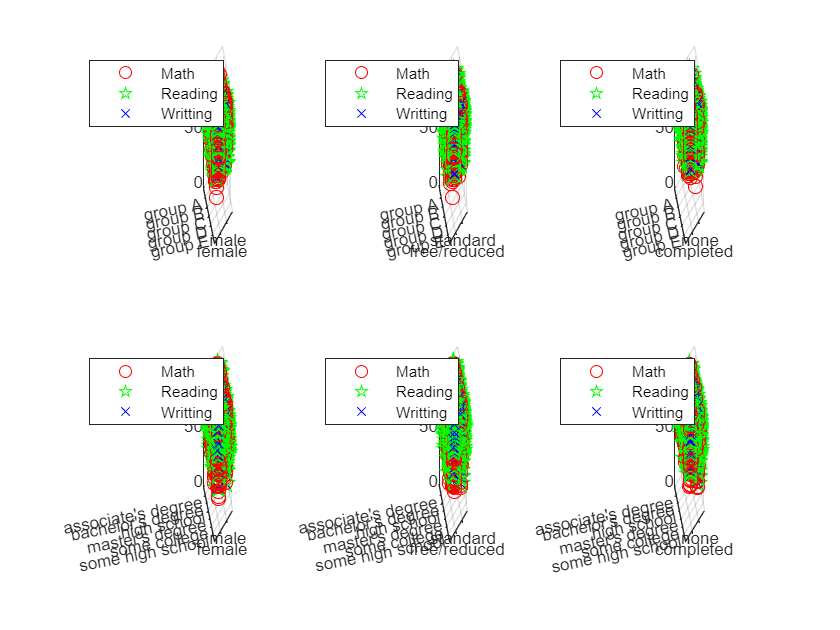

fig07 = figure;
subplot(2,3,1)
hold on
    x  = valRaza;
    y  = valGenero;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off

subplot(2,3,2)
hold on
    x  = valRaza;
    y  = valDesayuno;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off
subplot(2,3,3)
hold on
    x  = valRaza;
    y  = valPrecurso;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off
subplot(2,3,4)
hold on
    x  = valPadres;
    y  = valGenero;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off

subplot(2,3,5)
hold on
    x  = valPadres;
    y  = valDesayuno;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off
subplot(2,3,6)
hold on
    x  = valPadres;
    y  = valPrecurso;
    zM = math;
    zR = reading;
    zW = writing;
    swarmchart3(x,y,zM,50,'red','o')
    swarmchart3(x,y,zR,100,'green','pentagram')
    swarmchart3(x,y,zR,50,'blue','x')
    grid on
    legend('Math','Reading','Writting')
    view([60 30])
hold off

%Tablas
%dsStudents_1
%Variables categoricas
%valGenero 2cat
%valRaza 5cat
%valPadres 5cat
%valDesayuno 2cat
%valPrecurso 2cat
%%%
%Etiquetas de variables
%labelsGenero
%labelsRaza
%labelsPadres
%labelsDesayuno
%labelsPrecurso
%%%
%Variables numéricas
%math
%reading
%writing

mathAE    = [dsStudents_1.mathScore(valRaza == 'group B');      dsStudents_1.mathScore(valRaza == 'group C');dsStudents_1.mathScore(valRaza == 'group D')];
readingAE = [dsStudents_1.readingScore(valRaza == 'group B');dsStudents_1.readingScore(valRaza == 'group C');dsStudents_1.readingScore(valRaza == 'group D')];
writingAE = [dsStudents_1.writingScore(valRaza == 'group B');dsStudents_1.writingScore(valRaza == 'group C');dsStudents_1.writingScore(valRaza == 'group D')];

generoAE  = [dsStudents_1.gender(valRaza == 'group B'); dsStudents_1.gender(valRaza == 'group C'); dsStudents_1.gender(valRaza == 'group D')];
pruebaAE  = [dsStudents_1.testPreparation(valRaza == 'group B'); dsStudents_1.testPreparation(valRaza == 'group C'); dsStudents_1.testPreparation(valRaza == 'group D')];
desayunoAE  = [dsStudents_1.lunch(valRaza == 'group B'); dsStudents_1.lunch(valRaza == 'group C'); dsStudents_1.lunch(valRaza == 'group D')];
tableDataVF = table(generoAE,pruebaAE,desayunoAE,mathAE,readingAE,writingAE)

tableDataVF = 778×6 table
    generoAE    pruebaAE      desayunoAE     mathAE    readingAE    writingAE
    ________    _________    ____________    ______    _________    _________
     male       none         free/reduced      70         70           63    
     female     none         standard          46         61           58    
     male       none         standard          74         69           69    
     male       none         standard          53         50           49    
     male       none         free/reduced      76         74           76    
     female     none         standard          70         71           71    
     male       none         standard          74         83           72    
     female     completed    standard          80         81        

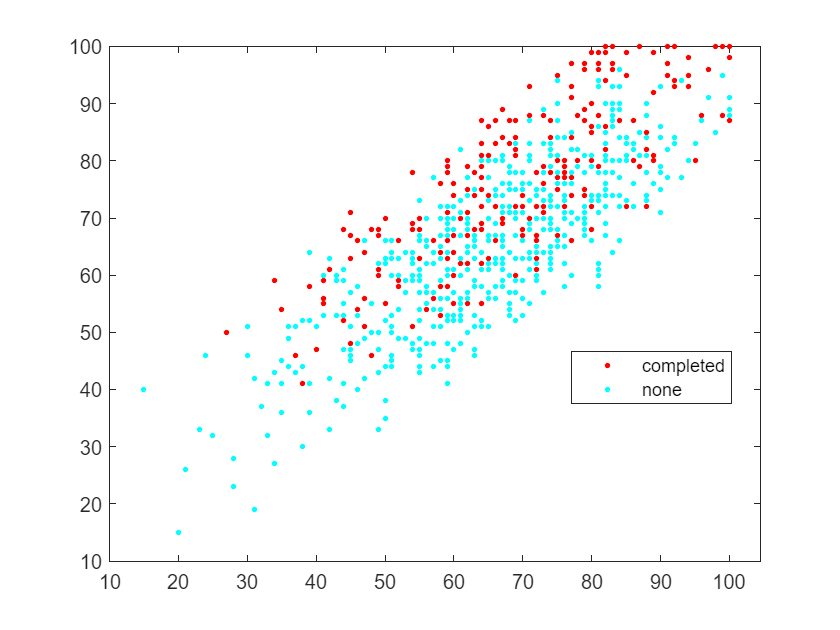

fig09=figure;
gscatter(tableDataVF.mathAE,tableDataVF.writingAE,tableDataVF.pruebaAE)

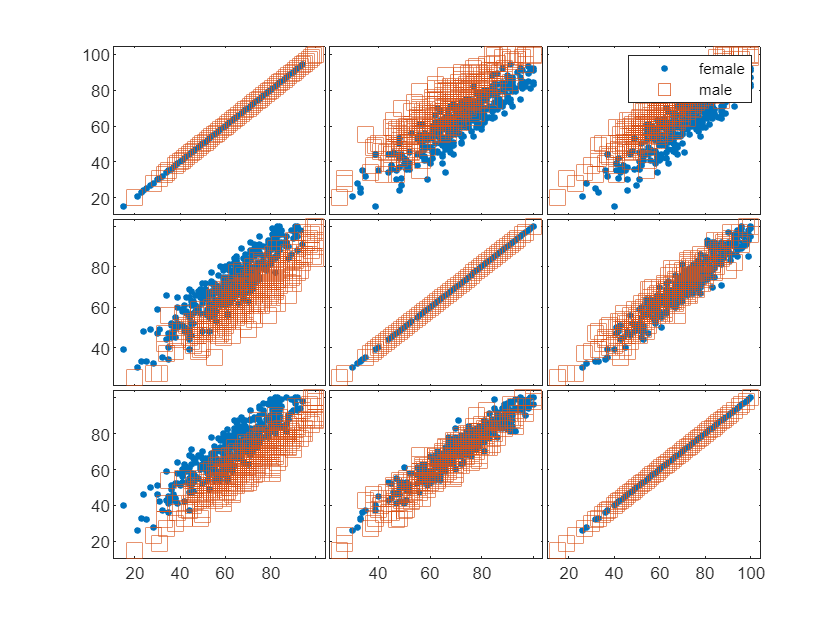

valGenero = tableDataVF.generoAE;
xVar = [mathAE, readingAE, writingAE];
yVar = [mathAE, readingAE, writingAE];
xnames = {'math';'reading';'writing'};
fig09=figure;
gplotmatrix(xVar,yVar,valGenero,colors,'.s',10)

XTotal=[tableDataVF.mathAE, tableDataVF.readingAE];
tam = size(XTotal,1);
PD = 0.3;
index = cvpartition(tam,'holdout',PD)

index = Hold-out cross validation partition
   NumObservations: 778
       NumTestSets: 1
         TrainSize: 545
          TestSize: 233

pTrain = XTotal(index.training, :);
pTest = XTotal(index.test, :);
size(pTrain)

ans =    545     2


size(pTest)

ans =    233     2


X=pTrain;

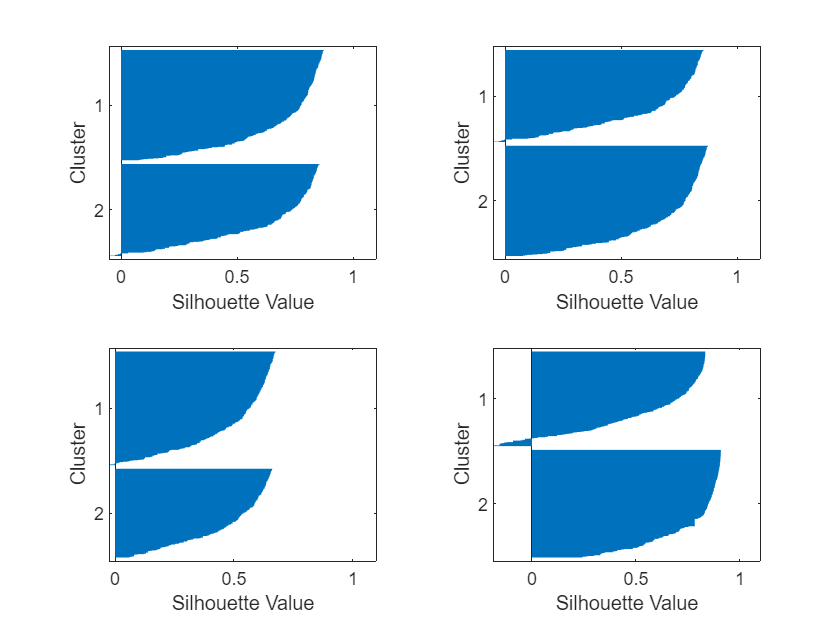

%X=[tableDataVF.mathAE, tableDataVF.readingAE];
%cat = [tableDataVF.generoAE];
%
num = 2;
[grp,C] = kmeans(X,2);
%eva = evalclusters(X,"kmeans","silhouette",...
%    "KList",2,"Distance","cosine")
%num = eva.OptimalK
[grp1,C1] = kmeans(X,num,"Distance","sqeuclidean");
[grp2,C2] = kmeans(X,num,"Distance","cityblock");
[grp3,C3] = kmeans(X,num,"Distance","cosine");
%[grp4,C4] = kmeans(X,2,"Distance","correlation");
%[grp5,C5] = kmeans(X,2,"Distance","hamming");

fig10a=figure;
tiledlayout(2,2);
nexttile
    axis square
    title('Automatico')
    silhouette(X,grp)
nexttile
    axis square
    title('sqeuclidean')
    silhouette(X,grp1,"sqEuclidean")
nexttile
    axis square
    title('cityblock')
    silhouette(X,grp2,"cityblock")
nexttile
    axis square
    title('cosine')
    silhouette(X,grp3,"cosine")

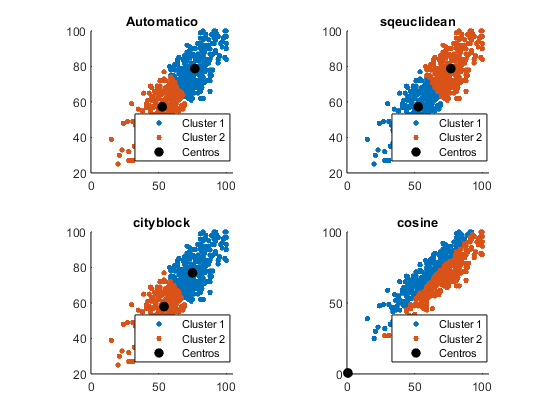

fig10b=figure;
tiledlayout(2,2);
nexttile
hold on
    axis square
    title('Automatico')
    gscatter(X(:,1),X(:,2),grp,colors)
    plot(C(:,1),C(:,2),'.k','MarkerSize',25)
    legend('Cluster 1','Cluster 2','Centros')
hold off
nexttile
hold on
    axis square
    title('sqeuclidean')
    gscatter(X(:,1),X(:,2),grp1,colors)
    plot(C1(:,1),C1(:,2),'.k','MarkerSize',25)
    legend('Cluster 1','Cluster 2','Centros')
hold off
nexttile
hold on
    axis square
    title('cityblock')
    gscatter(X(:,1),X(:,2),grp2,colors)
    plot(C2(:,1),C2(:,2),'.k','MarkerSize',25)
    legend('Cluster 1','Cluster 2','Centros')
hold off
nexttile
hold on
    axis square
    title('cosine')
    gscatter(X(:,1),X(:,2),grp3,colors)
    plot(C3(:,1),C3(:,2),'.k','MarkerSize',25)
    legend('Cluster 1','Cluster 2','Centros')
hold off

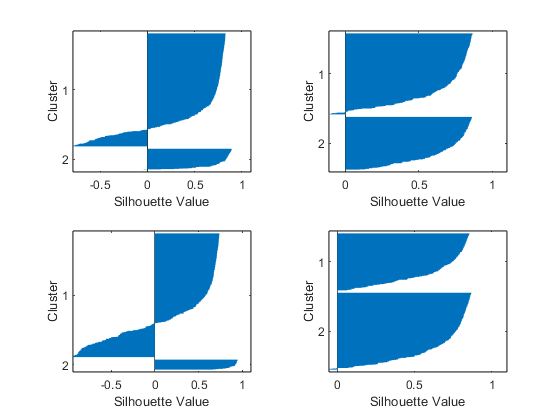

mdl = fitgmdist(X,2,...
                   'RegularizationValue',0.1,...
                   'CovarianceType','full',...
                   'SharedCovariance',true,...
                   'MaxIter',1000);
mdl1 = fitgmdist(X,2,...
                   'RegularizationValue',0.1,...
                   'CovarianceType','diagonal',...
                   'SharedCovariance',true,...
                   'MaxIter',1000);
mdl2 = fitgmdist(X,2,...
                   'RegularizationValue',0.1,...
                   'CovarianceType','full',...
                   'SharedCovariance',false,...
                   'MaxIter',1000);
mdl3 = fitgmdist(X,2,...
                   'RegularizationValue',0.1,...
                   'CovarianceType','diagonal',...
                   'SharedCovariance',false,...
                   'MaxIter',1000);



%mdl1 = fitgmdist(X,2,'RegularizationValue',0.1,"CovarianceType","diagonal","Replicates",5);
%threshold = [0.49 0.51];
%P = posterior(mdl,X);
%n = size(X,1);
%[~,order] = sort(P(:,1));
%figure
%plot(1:n,P(order,1),'r-',1:n,P(order,2),'b-')
%legend({'Cluster 1', 'Cluster 2'})
%idx = cluster(mdl,X);
%idxBoth = find(P(:,1)>=threshold(1) & P(:,1)<=threshold(2)); 
%numInBoth = numel(idxBoth)
%figure
%gscatter(X(:,1),X(:,2),idx,'rb','+o',5)
%hold on
%plot(X(idxBoth,1),X(idxBoth,2),'ko','MarkerSize',10)

grp = cluster(mdl,X);
grp1 = cluster(mdl1,X);
grp2 = cluster(mdl2,X);
grp3 = cluster(mdl3,X);

fig11a=figure;
tiledlayout(2,2);
nexttile
    axis square
    silhouette(X,grp)

nexttile
    axis square
    silhouette(X,grp1)
nexttile
    axis square
    silhouette(X,grp2)
nexttile
    axis square
    silhouette(X,grp3)

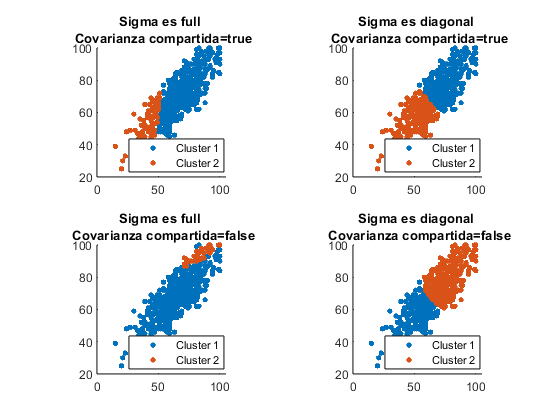


fig11b=figure;
tiledlayout(2,2);
nexttile
hold on
    axis square
    title(sprintf('Sigma es full \n Covarianza compartida=true'))
    gscatter(X(:,1),X(:,2),grp,colors)
    legend('Cluster 1','Cluster 2')
hold off
nexttile
hold on
    axis square
    title(sprintf('Sigma es diagonal \n Covarianza compartida=true'))
    gscatter(X(:,1),X(:,2),grp1,colors)
    legend('Cluster 1','Cluster 2')
hold off
nexttile
hold on
    axis square
    title(sprintf('Sigma es full \n Covarianza compartida=false'))
    gscatter(X(:,1),X(:,2),grp2,colors)
    legend('Cluster 1','Cluster 2')
hold off
nexttile
hold on
    axis square
    title(sprintf('Sigma es diagonal \n Covarianza compartida=false'))
    gscatter(X(:,1),X(:,2),grp3,colors)
    legend('Cluster 1','Cluster 2')
hold off

M='cosine';
Z1 = linkage(X);
Z2 = linkage(X,'average',M);
Z3 = linkage(X,'centroid',M);

Z4 = linkage(X,'complete',M);
Z5 = linkage(X,'median',M);

Z6 = linkage(X,'single',M);
Z7 = linkage(X,'ward',M);

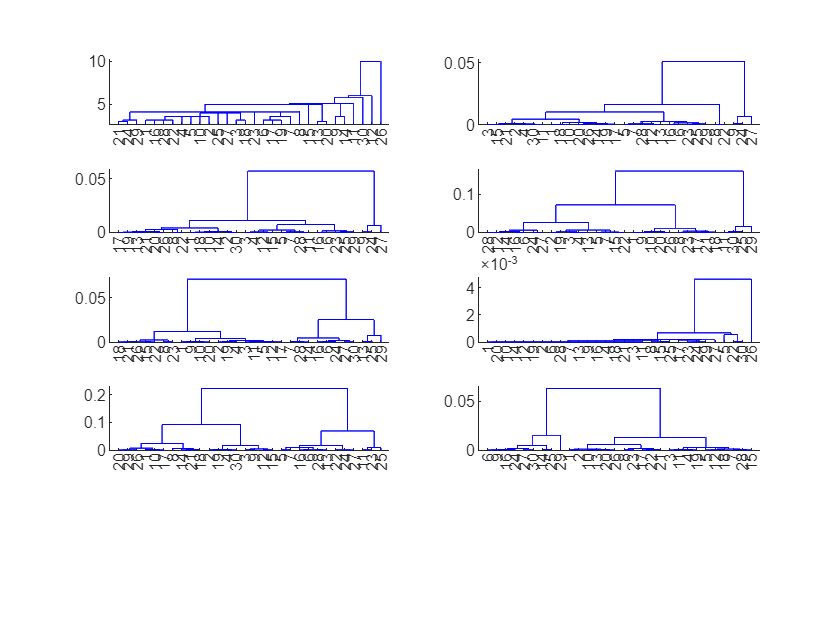

Z8 = linkage(X,'weighted',M);

fig12=figure;
subplot(5,2,1)
    dendrogram(Z1)
subplot(5,2,2)
    dendrogram(Z2)
subplot(5,2,3)
    dendrogram(Z3)
subplot(5,2,4)
    dendrogram(Z4)
subplot(5,2,5)
    dendrogram(Z5)
subplot(5,2,6)
    dendrogram(Z6)
subplot(5,2,7)
    dendrogram(Z7)
subplot(5,2,8)
    dendrogram(Z8)


grp1 = cluster(Z1,'maxclust',2);
D1 = pdist(X);
c1 = cophenet(Z1,D1)

c1 = 0.5752


grp2 = cluster(Z2,'maxclust',2);
D2 = pdist(X);
c2 = cophenet(Z2,D2)

c2 = 0.2305


grp3 = cluster(Z3,'maxclust',2);
D3 = pdist(X);
c3 = cophenet(Z3,D3)

c3 = 0.2138


grp4 = cluster(Z4,'maxclust',2);
D4 = pdist(X);
c4 = cophenet(Z4,D4)

c4 = 0.1583


grp5 = cluster(Z5,'maxclust',2);
D5 = pdist(X);
c5 = cophenet(Z5,D5)

c5 = 0.2129


grp6 = cluster(Z6,'maxclust',2);
D6 = pdist(X);
c6 = cophenet(Z6,D6)

c6 = 0.1645


grp7 = cluster(Z7,'maxclust',2);
D7 = pdist(X);
c7 = cophenet(Z7,D7)

c7 = 0.1830


grp8 = cluster(Z8,'maxclust',2);
D8 = pdist(X);
c8 = cophenet(Z8,D8)

c8 = 0.2170

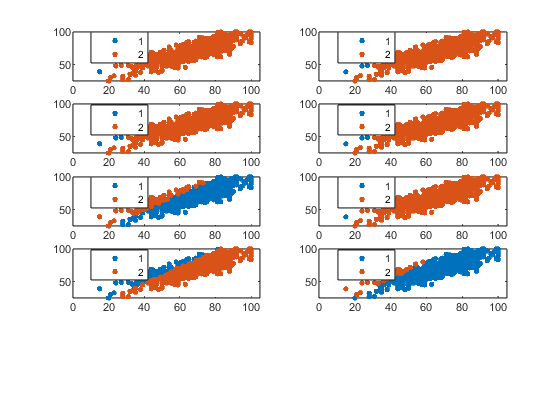



fig13=figure;
subplot(5,2,1)
    gscatter(X(:,1),X(:,2),grp1,colors)
     
subplot(5,2,2)
    gscatter(X(:,1),X(:,2),grp2,colors)
     
subplot(5,2,3)
    gscatter(X(:,1),X(:,2),grp3,colors)
     
subplot(5,2,4)
    gscatter(X(:,1),X(:,2),grp4,colors)
     
subplot(5,2,5)
    gscatter(X(:,1),X(:,2),grp5,colors)

subplot(5,2,6)
    gscatter(X(:,1),X(:,2),grp6,colors)
     
subplot(5,2,7)
    gscatter(X(:,1),X(:,2),grp7,colors)
     
subplot(5,2,8)
    gscatter(X(:,1),X(:,2),grp8,colors)